## **Progetto del corso di Controllo Avanzato Multivariabile**

#### Progettazione di un MPC per il controllo di un 

#### Continuous-flow Stirred-Tank Reactor (CSTR)

Wasim Essbai, Matteo Verzeroli

Prof. Antonio Ferramosca

Dott. Marco Polver

## 0. Setup

clear;
clc;
close all
set(0,'DefaultLineLineWidth', 1.5);
set(0,'defaultAxesFontSize', 14)
%set(0,'DefaultFigureWindowStyle', 'docked') 
set(0,'DefaultFigureWindowStyle', 'normal')
set(0,'defaulttextInterpreter','latex')
rng('default');

## 1. Parametri del reattore

q0 = 10;
V = 150;
k0 = 7.2*10^(10);
ER = 8750;
dHr = -50000;
UA = 50000;
ro = 1000;
Cp = 0.239;
tau_c = 1.5;
CAf = 1;
Tf = 370;

## 2. Equazioni di stato


$$\dot C_A(t) = \frac {q_o} V \cdot (C_{Af}-C_A(t))-k_0 \cdot exp(- \frac E {R\cdot T(t)})\cdot C_A(t)$$



$$\dot T(t) = \frac {q_o} V \cdot (T_{f}-T(t))+\frac {(-\Delta H_r)\cdot k_0} {\rho \cdot C_p} \cdot exp(- \frac E {R\cdot T(t)})\cdot C_A(t) + \frac {UA} {V\cdot \rho \cdot C_p} \cdot (T_c(t)-T(t))$$



$$\dot T_c(t) =\frac {T_r(t) - T_c(t)} {\tau_c}$$


## 3a. Linearazzazione del sistema

% Stato di equilibrio
Ca_eq = 0.5054;
T_eq = 315.5491;
Tc_eq = 308;

% Ingresso di equilibrio
Tr_eq = 308;

% Matrici del sistema tangente

A_c = [-k0*exp(-ER/T_eq) - q0/V, -Ca_eq*ER*k0*exp(-ER/T_eq)/(T_eq^2), 0;
      ((-dHr)*k0/(ro*Cp))*exp(-ER/T_eq), -q0/V + Ca_eq*((-dHr)*k0/(ro*Cp))*exp(-ER/T_eq)*ER/(T_eq^2) - UA/(V*ro*Cp), UA/(V*ro*Cp);
      0, 0, -1/tau_c];
B_c = [0;0;1/tau_c];
C_c = [1, 0, 0]; % si assume Ca come uscita del sistema
D_c = 0;

continuous_time_ss = ss(A_c,B_c,C_c,D_c);

## 3b. Discretizzazione del sistema linearizzato

Ts = 1; % tempo di campionamento

discrete_time_ss = c2d(continuous_time_ss, Ts);

A = discrete_time_ss.A;
B = discrete_time_ss.B;
C = discrete_time_ss.C;
D = discrete_time_ss.D;

% Matrice di raggiungibilità
Mr = ctrb(discrete_time_ss);
Mr_rank = rank(Mr);

% Autovalori del sistema
lambda0 = eig(A);

## 4. Vincoli sul sistema linearizzato

% Vincoli sullo stato
Hx = [1,0,0;
      -1,0,0;
      0,1,0;
      0,-1,0;
      0,0,1;
      0,0,-1];
hx = [0.954 - Ca_eq; -0.38 + Ca_eq; 10^6; 10^6; 10^6; 10^6];

% Vincoli sull'ingresso
Hu = [1;-1];
hu = [310 - Tr_eq; -280 + Tr_eq];

## 5. Invariant set per il sistema controllato

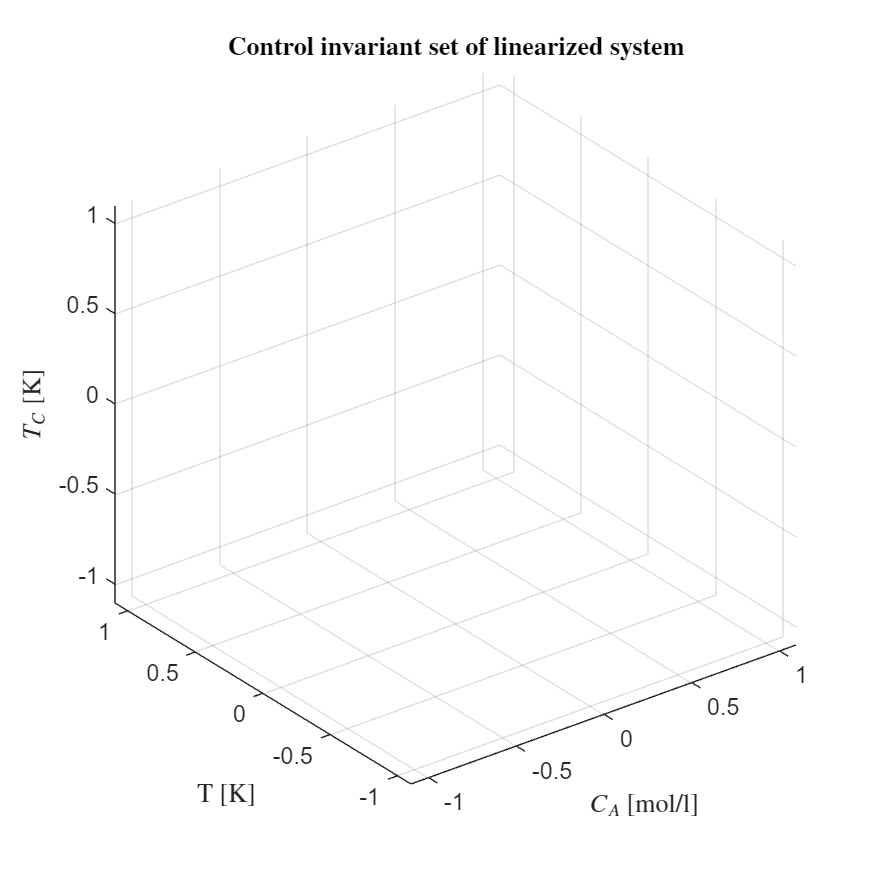

% Matrici del costo quadratico
Q = eye(3);
R = 1;

%   Computazione control invariant set
CIS_H = [1,0,0;
      -1,0,0;
      0,1,0;
      0,-1,0;
      0,0,1;
      0,0,-1];
CIS_h = [0; 0; 0; 0; 0; 0];

CIS = Polyhedron(CIS_H,CIS_h);

figure('Position', [0 0 1000 1000])
CIS.plot('color', 'lightgreen');
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

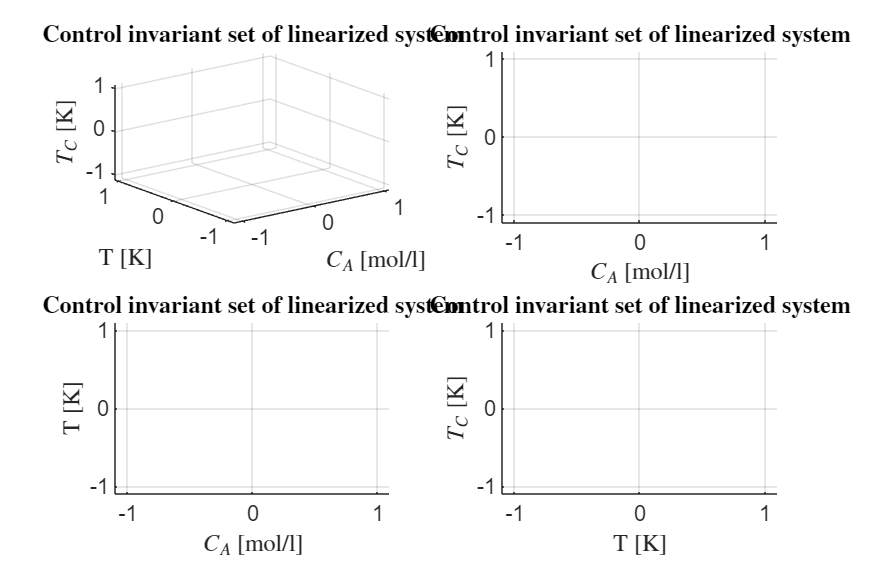


%exportgraphics(gcf,'CIS.png','Resolution',600);
figure('Position', [0 0 2000 1300])
subplot(2,2,1);
CIS.plot('linewidth',0.5);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

subplot(2,2,2);
CIS.plot('linewidth',0.01);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 0])

subplot(2,2,3);
CIS.plot('linewidth',0.01);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 90])

subplot(2,2,4);
CIS.plot('linewidth',0.01);
title('\textbf{Control invariant set of linearized system}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([90 0])


%exportgraphics(gcf,'CIS-views.png','Resolution',600);

## 6. N-step-controllable set dell'invariant set

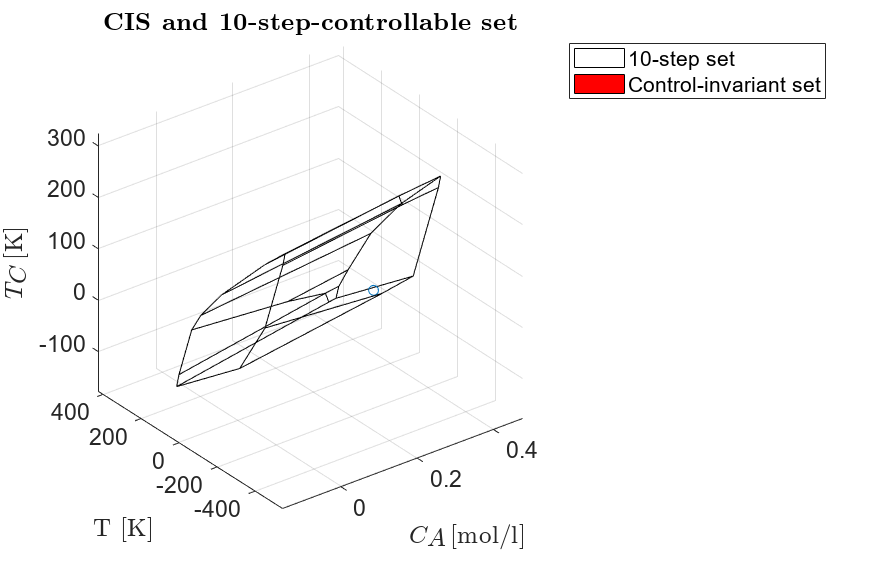

%   Orizzonte di predizione
N = 16; %limite è 15

[Np_steps_H, Np_steps_h] = controllable_set(Hx,hx,Hu,hu,CIS_H,CIS_h,A,B,N);
Np_step_set = Polyhedron('A',Np_steps_H,'b',Np_steps_h);

figure('Position', [0 0 2000 1300])
Np_step_set.plot('Alpha',0,'linewidth',0.5);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.1)

scatter3([0.347600000000000],[-18.5631000000000],[-16])

legend({'10-step set', 'Control-invariant set'});

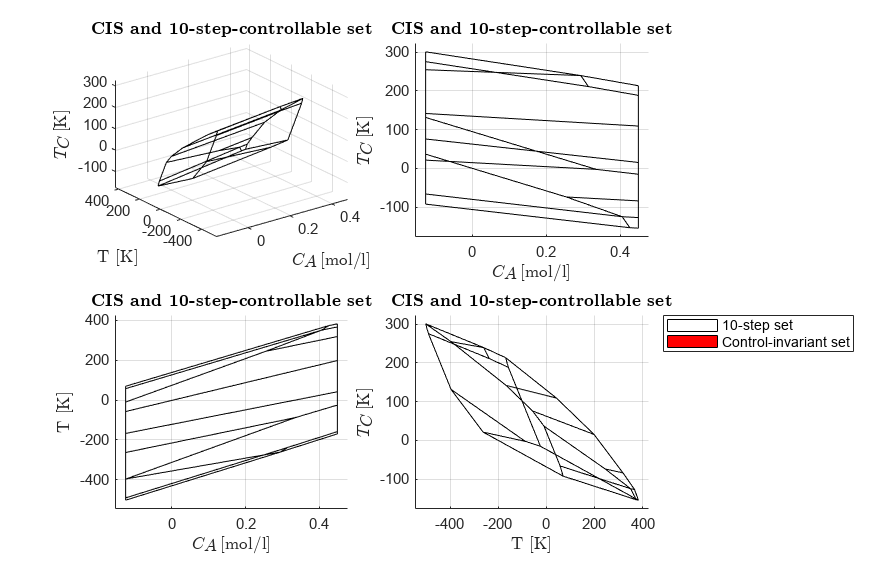


%exportgraphics(gcf,'CIS-10step-CS.png','Resolution',600);
figure('Position', [0 0 2000 1300])

tiledlayout('flow','TileSpacing','compact');
nexttile

Np_step_set.plot('Alpha',0,'linewidth',0.5);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.1)

nexttile
Np_step_set.plot('Alpha',0,'linewidth',0.4);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.01)
view([0 0])

nexttile
Np_step_set.plot('Alpha',0,'linewidth',0.4);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.01)
view([0 90])

nexttile
Np_step_set.plot('Alpha',0,'linewidth',0.4);
title('\textbf{CIS and 10-step-controllable set}');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
hold on;
CIS.plot('linewidth',0.01) 
view([90 0])

leg = legend({'10-step set', 'Control-invariant set'});

leg.Location(1);

%exportgraphics(gcf,'CIS-10step-CS-views.png','Resolution',600);

## 6. Design MPC e simulazione

%   Numero di step simulati
T_sim = 60;

%   Riferimento
x_ref = [Ca_eq; T_eq; Tc_eq];
u_ref = Tr_eq;

x_ref_lin = [0; 0; 0];
u_ref_lin = 0;

mpc = mpc_ingredients(A,B,Hx,hx,Hu,hu,CIS_H,CIS_h,x_ref_lin,u_ref_lin,Q,R,N);

%   Log stati e ingresso sistema
x_log = zeros(3,T_sim+1);
u_log = zeros(1,T_sim);
flags = zeros(1,T_sim);

x_log(:,1) = [0.853; 296.986; 292]; % condizione iniziale

if Np_step_set.contains(x_log(:,1) - x_ref)

%x_log(:,1) = [0.853; 270; 280]; Non dovrebbe funzionare con N<=3

    for tt = 1:T_sim
    
        %   Stato sistema linearizzato
        x_lin = x_log(:,tt) - [Ca_eq; T_eq; Tr_eq];
        x_lin_shifted = x_lin - x_ref_lin;
    
        %   Impostazioni MPC relative alla condizione iniziale
        f = mpc.f_base * x_lin_shifted;
        b_ineq = mpc.b_ineq_base - mpc.b_ineq_x0_factor * x_lin_shifted;
        
        %   Risoluzione problema di ottimizzazione
        [delta_u_seq,~,exitflag] = quadprog(mpc.F,f,mpc.A_ineq,b_ineq);
    
        flags(tt) = exitflag;
    
        %   Risposta del sistema
        u_log(tt) = u_ref + delta_u_seq(1);
        
        dxdt = @(t,x) cstr(t,x,u_log(tt),q0,V, k0, ER, dHr, UA, ro, Cp, tau_c, CAf, Tf);
        [~,xx] = ode45(dxdt,[0 Ts],x_log(:,tt));
        x_log(:,tt+1) = xx(end,:)';
    end
else
    disp("ERRORE!!!")
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## 8. Plot dei risultati

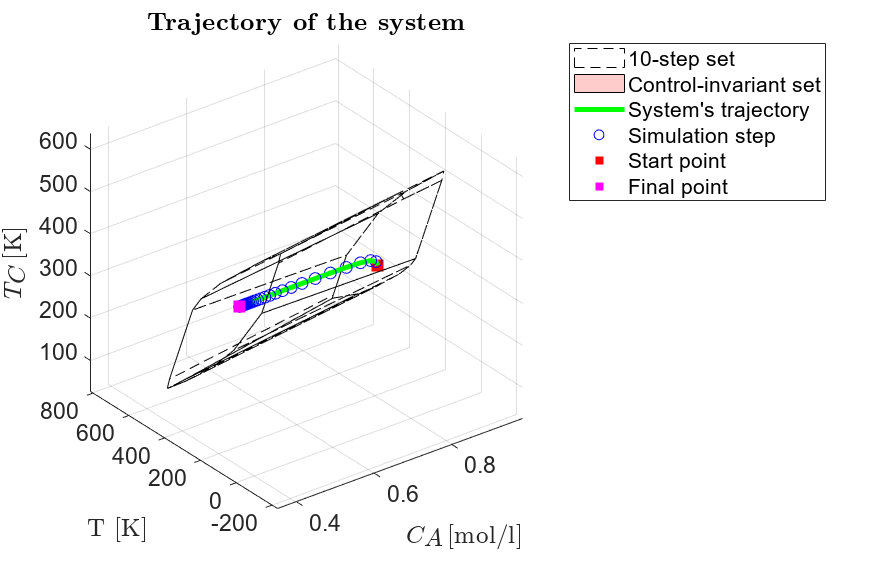

%   Traslazione del CIS e dell'N-step set nelle coordinate originali
CIS_shifted = CIS + x_ref;
Np_step_set_shifted = Np_step_set + x_ref;

figure('Position', [0 0 2000 1300])
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step', 'Start point', 'Final point'});

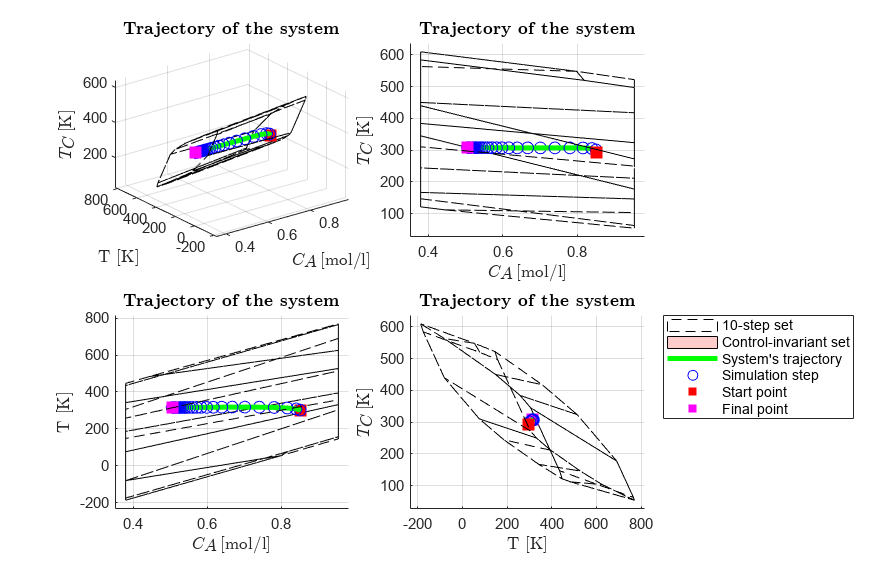

%exportgraphics(gcf,'MPC.png','Resolution',600);


figure('Position', [0 0 2000 1300])

tiledlayout('flow','TileSpacing','compact');
nexttile

Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');

nexttile
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 0])

nexttile
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');
zlabel('$T_C$ [K]');
view([0 90])

nexttile
Np_step_set_shifted.plot('Alpha',0, 'linestyle', '--', 'linewidth', 0.1);
title('\textbf{Trajectory of the system}');
hold on;
CIS_shifted.plot('Alpha', 0.2,'linewidth', 0.1);
hold on
plot3(x_log(1,:),x_log(2,:),x_log(3,:),'Color',[0 1 0], 'LineWidth', 3)
scatter3(x_log(1,2:end-1),x_log(2,2:end-1), x_log(3,2:end-1), 50,'blue');
scatter3(x_log(1,1),x_log(2,1), x_log(3,1), 80,'red','filled','square');
scatter3(x_log(1,end),x_log(2,end), x_log(3,end), 80,'magenta','filled','square');
xlabel('$C_A$ [mol/l]');
ylabel('T [K]');    
zlabel('$T_C$ [K]');
view([90 0])

leg = legend({'10-step set', 'Control-invariant set', 'System''s trajectory', 'Simulation step', 'Start point', 'Final point'});

leg.Location(1);
%exportgraphics(gcf,'MPC-view.png','Resolution',600);

## 8.1 Plot degli stati e dell'ingresso

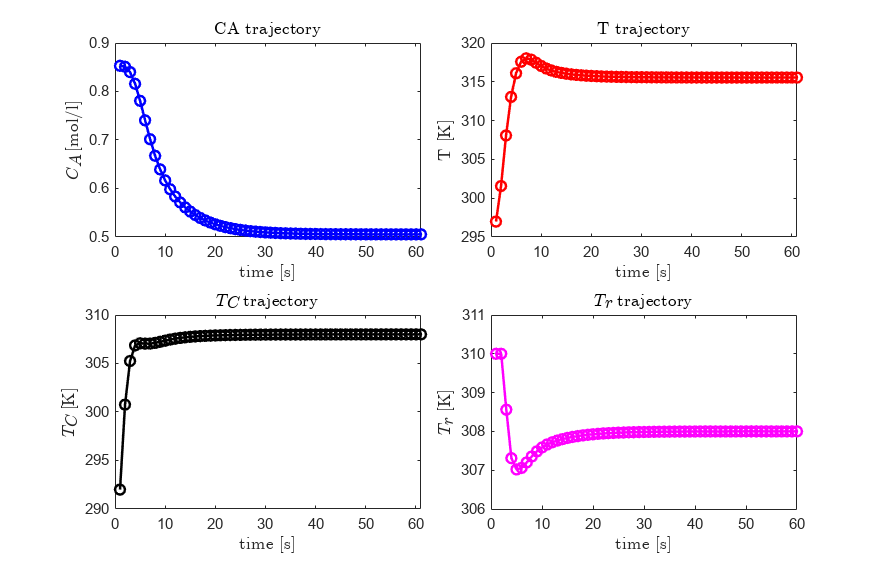

figure('Position', [0 0 2000 1300])

tiledlayout('flow','TileSpacing','compact');
nexttile

plot(x_log(1,:),'-o','Color','blue')
title('CA trajectory')
xlabel('time [s]');
ylabel('$C_A$ [mol/l]');

nexttile

plot(x_log(2,:),'-o', 'Color', 'red')
title('T trajectory')
xlabel('time [s]');
ylabel('T [K]');

nexttile

plot(x_log(3,:),'-o', 'Color','black')
title('$T_C$ trajectory')
xlabel('time [s]');
ylabel('$T_C$ [K]');
ylim([290 310])

nexttile

plot(u_log(1,:),'-o', 'Color', 'magenta')
title('$T_r$ trajectory')
xlabel('time [s]');
ylabel('$T_r$ [K]');
ylim([306 311])

%exportgraphics(gcf,'states-input-1s.png','Resolution',300);

x_k = x_log(:,tt);
for i=2:15    
    u_ap = u_ref + delta_u_seq(i);
    
    dxdt = @(t,x) cstr(t,x,u_ap,q0,V, k0, ER, dHr, UA, ro, Cp, tau_c, CAf, Tf);
    [~,xx] = ode45(dxdt,[0 Ts],x_k);
    x_k = xx(end,:)';
    x_k_lin = x_k-x_ref;
end